# **Pràctica 3: Disseny i implementació de controladors PID**

Les pràctiques de l’assignatura Control amb Computador consisteixen en l’estudi d’un servomecanisme de posicionament angular controlat per un PC. Les sessions de laboratori P1 i P2 es centren, respectivament, en l’anàlisi experimental de les respostes temporal i freqüencial del sistema. Les sessions P3 i P4 es dediquen al disseny de controladors PID. Finalment, en la pràctica P5 es dissenyaran controladors en camp freqüencial.

**OBJECTIU: Dissenyar un controlador PID de la posició de l'eix de sortida per la planta estudiada en les sessions anteriors per tal que el sistema en llaç tancat complixi unes certes especificacions.**

**En aquesta sessió l'estudiant ha de:**

- **Dissenyar un PI y un PID per assignació de pols.**

- **Verificar experimentalment els sistemes de control dissenyats.**

% Canvi entre les dades de l'experiment i els del directori Resultats
% Si voleu utilitzar les dades del directori Resultats = false
% Si voleu utilitzar dades pròpies = true
useExperimentalData = false;

# Exercici 11: Disseny i verificació experimental d'un PI per assignació de pols.

Dissenyar un PI de control de velocitat que faci que la resposta temporal a un graó de entrada no presenti sobrepuigs i que el temps d'establiment (amb el criteri del 2%) sigui de 0.9 segons. Per a la simulació del controlador PI digital, obrir i executar el model P3_Ex11a.slx. Per a la seva comprovació amb el motor, obrir i executar el model P3_Ex11b.slx.

% planta
K0=0.82;
tau0=0.26;

% Temps de mostratge
Ts=0.01;

% Especificacions
xi=1;
ts_2=0.9; % Temps d'establiment amb el criteri del 2%
Tdes=ts_2/4;
wn=5.8/(xi*ts_2);

% Disseny del controlador
Zdes=exp(-Ts/Tdes);
alpha=exp(-Ts/tau0);
beta=-2*exp(-Ts*xi*wn)*cos(wn*Ts*sqrt(1-xi^2));
gamma=exp(-2*Ts*xi*wn);

Ki_star=(gamma-alpha+beta+(alpha+1))/(2*K0*(1-alpha));
Ki=(2/Ts)*Ki_star;
Kp=((beta+alpha+1)/(K0*(1-alpha)))-Ki_star;

Per a dissenyar el controlador, s'han seguit els següents passos. Primerament, s'ha digitalitzat la planta amb un mantenidor d'ordre zero i s'ha escollit un controlador PI discretitzat mitjançant l'aproximació trapezoïdal.


$$\textrm{motor}:G\left(z\right)=k_{\textrm{mot}} \frac{1-\alpha }{z-\alpha }\;\;\;\;\;\;\textrm{on}\;\;\;\;\;\;\alpha =e^{-\frac{T_s }{\tau_0 }}$$



$$\textrm{controlador}\;\textrm{PI}:\textrm{PI}\left(z\right)=k_p +k_i \frac{T_s }{2}\frac{z+1}{z-1}=k_p +k_i^* \frac{z+1}{z-1}\;\;\;\;\;\;\mathrm{on}\;\;\;\;k_i^* =k_i \frac{T_s }{2}$$


Tancant el llaç la funció de transferència pren la forma:


$$\textrm{l}c\left(z\right)=\frac{\textrm{PI}\left(z\right)G\left(z\right)}{1+\textrm{PI}\left(z\right)G\left(z\right)}=\frac{k_{\mathrm{mot}} \left(k_p +k_i^* \right)\left(z+\frac{k_i^* -k_p }{k_i^* +k_p }\right)\left(1-\alpha \right)}{\left(z-1\right)\left(z-\alpha \right)+k_{\mathrm{mot}} \left(k_p +k_i^* \right)\left(z+\frac{k_i^* -k_p }{k_i^* +k_p }\right)\left(1-\alpha \right)}$$


Igualant l'equació característica real, amb la ideal, podrem sintonitzar els nostres paràmetres.


$$\begin{array}{l}
\mathrm{eq}\;\mathrm{real}:z^2 +\left\lbrack \left(k_p +k_i^* \right)k_{\mathrm{mot}} \left(1-\alpha \right)-\left(\alpha +1\right)\right\rbrack z+\alpha +k_{\mathrm{mot}} \left(k_i^* -k_p \right)\left(1-\alpha \right)=0\\
\mathrm{eq}\;\mathrm{ideal}:z^2 -2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)z+e^{-2T_s \xi \omega_n } 
\end{array}$$


Amb la qual cosa, les equacions de sintonia serien:


$$\begin{array}{l}
k_p =\frac{-\left(-2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+e^{-2T_s \xi \omega_n } +1\right)}{T_s \;k_{\mathrm{mot}} \;\left(\alpha -1\right)}\\
k_i =\frac{-2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+e^{-2T_s \xi \omega_n } +1}{2{\;k}_{\mathrm{mot}} \;\left(\alpha -1\right)}-\frac{\alpha -2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+1}{k_{\mathrm{mot}} \;\left(\alpha -1\right)}
\end{array}$$


Les respostes ideal i real es poden observar en la següent imatge.

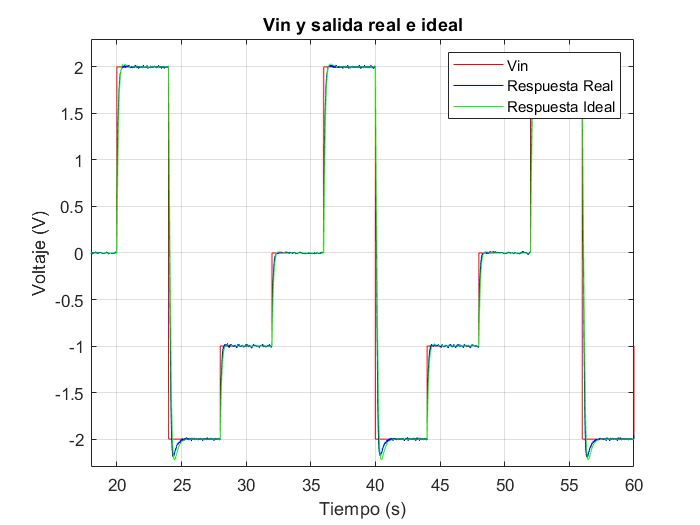

% Dibuixar la resposta del motor
if useExperimentalData
    % Utilitzar Simulink
    addpath([pwd filesep 'PIvel']);
    open PI_experimental.slx;
    run PI_experimental.slx;
else
    FileName   = 'PI_real_experimental.mat';
    cd('..')
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac3'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(PI_real_experimental.time,[PI_real_experimental.signals.values(:,1,:)],'r')
hold on; grid on;
plot(PI_real_experimental.time,[PI_real_experimental.signals.values(:,2,:)],'b')
plot(PI_real_experimental.time,[PI_real_experimental.signals.values(:,3,:)],'g')
xlim([18 60]); ylim([-2.3 2.3]);
xlabel('Temps (s)');
ylabel('Voltatge (V)');
title('Vin i sortida real i ideal');
legend('Vin','Resposta Real','Resposta Ideal');

Com es pot analitzar, les dues respostes són pràcticament iguals, però si analitzem les especificacions desitjades, podem observar que aquestes no es compleixen. Això passa perquè el controlador PI junt amb una planta de primer ordre tenen com a resposta un sistema amb dos pols i un zero. Aquest últim, té un efecte negatiu en la dinàmica del sistema, normalment fent-la una mica més ràpida del desitjat, és per això, que en aquest cas obtenim un petit sobrepuig. En la següent pràctica s'analitzarà com eliminar aquest efecte.

# Exercici 12: Disseny d'un PID per assignació de pols.

Dissenyeu un PID de control de posició que faci que la resposta temporal a un graó de entrada presenti un sobreimpuls del 80% i una freqüència de les oscil·lacions de 0,5 Hz.

Per aconseguir-ho calculeu el valor dels dos pols dominants que compleixen amb aquestes especificacions i considereu un tercer pol en 0,01. Preneu el període de mostratge Ts igual a 0,01s. Determineu el valor de $k_p$,$\;k_i$ y $k_d$ i del $4^{\mathrm{rt}}$ pol. Verifiqueu si es compleix la hipòtesi d'arrels dominants. 

% Paràmetres de la planta 
K0=0.82/0.017;
tau0=0.26;
N=9;
Kpot=1.62;

% Període de mostratge
Ts=0.01;

% Especificacions de control desitjades
Sp=80; % Sobrepuig
Fd=0.5; % freqüència

% Pols de segon ordre continu que compliran les especificacions
wd=2*pi*Fd ;
xi=sqrt((log(Sp/100))^2/(pi^2+log(Sp/100)^2))

xi = 0.0709

wn=wd/ sqrt(1-xi^2)

wn = 3.1495

s1=-xi*wn+j*wd

s1 = -0.2231 + 3.1416i

s2=-xi*wn-j*wd

s2 = -0.2231 - 3.1416i


% Pols de segon ordre discret que compliran les especificacions
p1=exp(Ts* s1 )

p1 = 0.9973 + 0.0313i

p2=exp(Ts* s2 )

p2 = 0.9973 - 0.0313i


% Inserir el tercer pol
p3=0.01

p3 = 0.0100


% Funció de transferència discreta de la planta 
Ptas=tf([K0*(1/N)*Kpot],[tau0,1,0]);
Ptaz=c2d(Ptas,Ts,'zoh');

% Coeficients del denominador i enumerador 
[Nz ,Dz]= tfdata(Ptaz,'v')

Nz =          0    0.0016    0.0016


Dz =     1.0000   -1.9623    0.9623


a1=Nz(2);
a0=Nz(3);
b1=Dz(2);
b0=Dz(3);

% Definicions de les matrius A i B
A=[-1 -a1 -a1 -a1 ; p2+p3+p1 a1-a0 -a1-a0 -a0+2*a1 ; ...
   -p1*p2-p3*p1-p2*p3 a0 -a0 2*a0-a1 ; p1*p2*p3 0 0 -a0 ] ;
b=[p1+p2+p3-1+b1 ; -p1*p2-p3*p1-p3*p2+b0-b1 ; p1*p2*p3-b0 ; 0 ] ;

% Controlador 
x=inv(A)*b ; 

p4=x(1)

p4 = 0.9475

Kp=x(2)

Kp = 0.3698

Ki=(2/Ts)*x(3)

Ki = 1.5691

Kd=Ts*x(4)

Kd = 0.0580


% Anti-wind-up
pawd=0.2;
Kaw=1/Ki;

% Càlcul de dominància dels pols
dominancia=log(abs(p4))/log(abs(p1))

dominancia = 24.1515

La funció de transferència del PID té la següent forma:


$$\textrm{controlador}\;\mathrm{PI}\textrm{D}:\textrm{P}\mathrm{ID}\left(z\right)=k_p +k_i \frac{T_s }{2}\frac{z+1}{z-1}+k_d \frac{z-1}{T_{s\;} z}=k_p +k_i^* \frac{z+1}{z-1}+k_d^* \;\frac{z-1}{z}\;\;\;\;\textrm{donde}\;\;\;\;k_i^* =k_i \frac{T_s }{2}\;\;y\;k_d^* =\frac{k_d }{T_s }$$



$$\textrm{planta}\;\textrm{seg}\mathrm{on}\;\textrm{ord}\mathrm{re}:G\left(z\right)=\frac{a_{1\;} z+a_0 }{z^2 +b_{1\;} z+b_0 }$$


Amb la qual cosa la funció de transferència de llaç tancat pren la forma:


$$\mathrm{cl}\left(z\right)=\frac{\mathrm{PID}\left(z\right)G\left(z\right)}{1+\mathrm{PID}\left(z\right)G\left(z\right)}=\frac{\mathrm{Num}\left(z\right)}{\mathrm{Den}\left(z\right)}$$


Es pot comprovar fàcilment que el denominador és:


$$\begin{array}{l}
\mathrm{Den}\left(z\right)=z^4 +\left(-1+k_i^* a_1 +b_1 +k_d^* a_1 +k_p a_1 \right)z^3 +\left(-b_1 -k_p a_1 +k_p a_0 +b_0 -2k_d^* a_1 +k_i^* a_0 +k_i^* a_1 +k_d^* a_0 \right)z^2 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left(k_i^* a_0 -b_0 -2k_d^* a_0 -k_p a_0 +k_d^* a_1 \right)z+k_d^* a_0 
\end{array}$$


El polinomi és de quart ordre, per tant tindrà quatre arrels i l'equació característica serà:


$$\begin{array}{l}
\mathrm{Den}\left(z\right)=\left(z-p_1 \right)\left(z-p_2 \right)\left(z-p_3 \right)\left(z-p_4 \right)=z^4 +\left(-p_1 {-p}_2 -p_3 -p_4 \right)z^3 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left(p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 -\left(-p_1 -p_2 -p_3 \right)p_4 \right)z^2 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left({-p}_1 p_2 p_3 -\left(p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 \right)p_4 \right)z+p_1 p_2 p_3 p_4 
\end{array}$$


Com és un sistema de quart ordre i tres incògnites, no es podran fixar tots els pols del sistema, és a dir un d'ellos quedarà lliure ($p_4$). Per tal que la metodologia sigui acceptable i adequada el pol lliure $p_4$ ha d'ésser estable i no dominant.

Igualant els coeficients i representant-ho en forma matricial, el sistema en llaç tancat seria:


$$\left\lbrack \begin{array}{cccc}
-1 & -a_1  & -a_1  & -a_1 \\
p_1 +p_2 +p_3  & a_1 -a_0  & -a_1 -a_0  & -a_0 +2a_1 \\
-p_1 p_2 -p_3 p_1 -p_3 p_2  & a_0  & -a_0  & 2a_0 -a_1 \\
p_1 p_2 p_3  & 0 & 0 & -a_0 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
p_4 \\
k_p \\
k_i^* \\
k_d^* 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
p_1 +p_2 +p_3 -1+b_1 \\
-p_1 p_2 -p_3 p_1 -p_3 p_2 +b_0 -b_1 \\
p_1 p_2 p_3 -b_0 \\
0
\end{array}\right\rbrack$$


Aquest sistema lineal és fàcilment resoluble utilitzant MATLAB. L'equació és $A\;x=b$, on $A$ és una matriu $n\;x\;n$ i $b$ és un vector columna amb $n$ elements, llavors, $x=\mathrm{inv}\left(A\right)·b$.

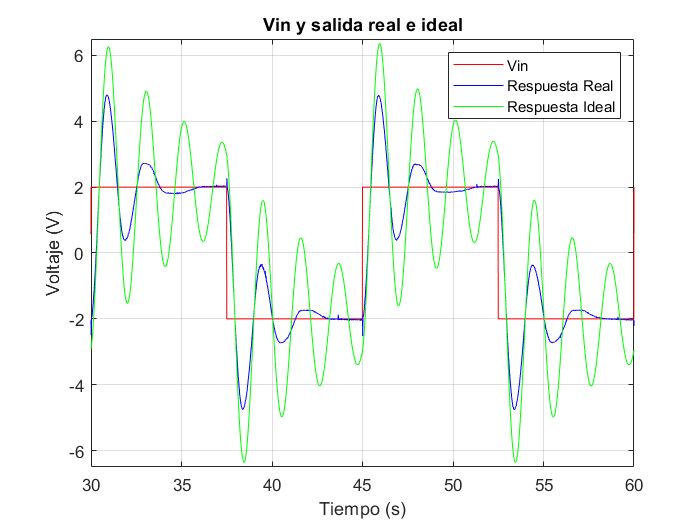

% Dibuixar la resposta del motor
if useExperimentalData
    % Utilitzar Simulink
    addpath([pwd filesep 'PIvel']);
    open PID_experimental.slx;
    run PID_experimental.slx;
else
    FileName   = 'PID_real_ideal.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac3'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(PID_real_ideal.time,[PID_real_ideal.signals.values(:,1,:)],'r')
hold on; grid on;
plot(PID_real_ideal.time,[PID_real_ideal.signals.values(:,2,:)],'b')
plot(PID_real_ideal.time,[PID_real_ideal.signals.values(:,3,:)],'g')
xlim([30 60]); ylim([-6.5 6.5]);
xlabel('Temps (s)');
ylabel('Voltatge (V)');
title('Vin i sortida real i ideal');
legend('Vin','Resposta Real','Resposta Ideal');

Com es pot observar, tot i que el controlador sigui capaç d'establir el sistema, les respostes real i ideal no són semblants. Això passa perquè un dels pols s'ha fixat lliurement i encara que compleixi la metodologia de ser lliure i no dominant, aquesta afecta el sistema. A més d'això, el controlador afegeix dos zeros, els quals també afecten a la dinàmica del sistema. Al costat de tot això cal afegir l'efecte que algunes dinàmiques no han estat modelades.

# Exercici 14: Dissenyar els mateixos controladors però amb el bloc PID de Simulink.

Saber com es dissenyen i dissenyar controladors PID és molt important, ja que serem capaços de fer un llaç de control per qualsevol sistema. Però a més d'això, hem de saber que MATLAB/Simulink ofereixen eines que simplifiquen la nostra feina. Per exemple, amb l'eina "*pidTuner*" podem obtenir els guanys $k_p$,$\;k_i$ y $k_d$ tenint solament la funció de transferència de la planta i les especificacions desitjades. D'altra banda, Simulink té un bloc específic anomenat "*PID Controller*" en el qual podem especificar els guanys de cada acció, coeficient del filtre de la part derivativa i el període de mostratge.

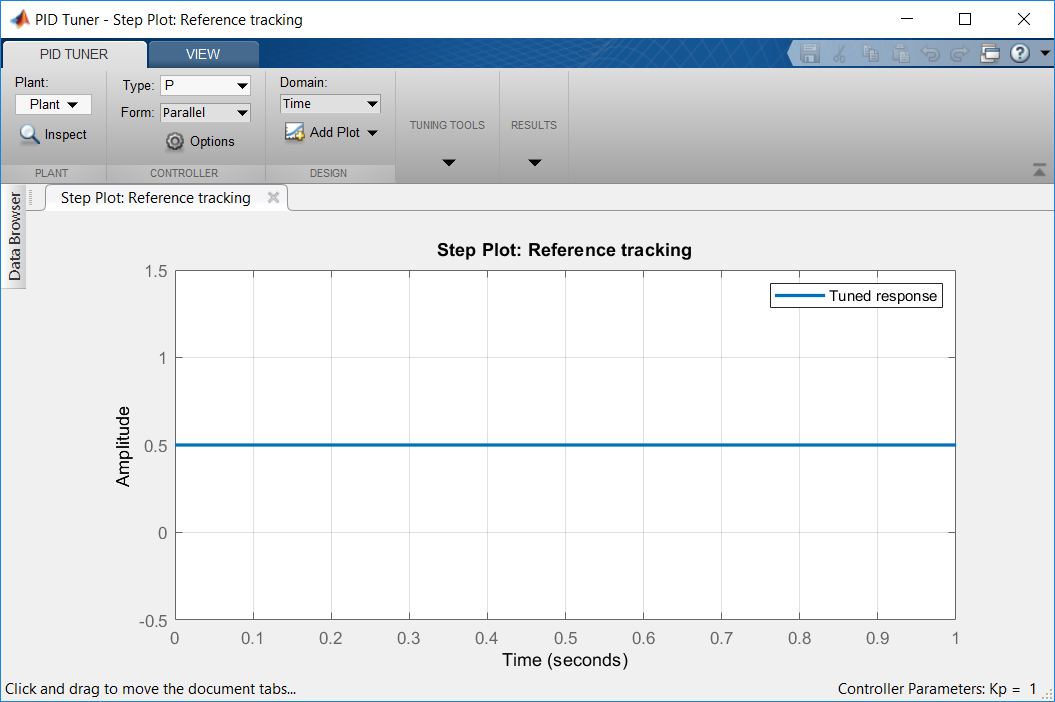

Figure 1: Eina pidTuner

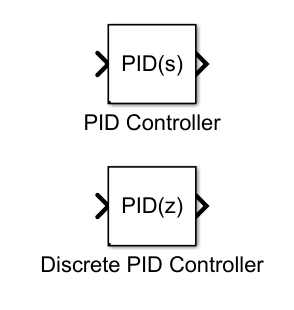

Figure 2: Blocs PID de Simulink

En aquest exercici es desitja implementar els mateixos controladors, però fent servir aquest bloc específic que ofereix Simulink. Per a la simulació del PI obrir i executar el model P3_Ex13a.slx. Per executar aquest model en una planta obrir i executar el model P3_Ex13b.slx. Per a la simulació del PID, obrir i executar el model P3_Ex13c.slx i per a la seva comprovació fer servir el model P3_Ex13d.slx. Analitzar que els resultats obtinguts en aquest exercici s'assemblen als resultats obtinguts en els exercicis anteriors.